**Uses a Normal Distribution to check calculations for mean and standard deviation.**

warning off
clear all
clc
addpath(genpath('../..'));


theta_full = pi/180:pi/180:2*pi;
mu = 54*pi/180; % mean
sigma = 10*pi/180; % sd
data_fab = normpdf(theta_full,mu,sigma);
data_fab = data_fab + circshift(data_fab', 180)';

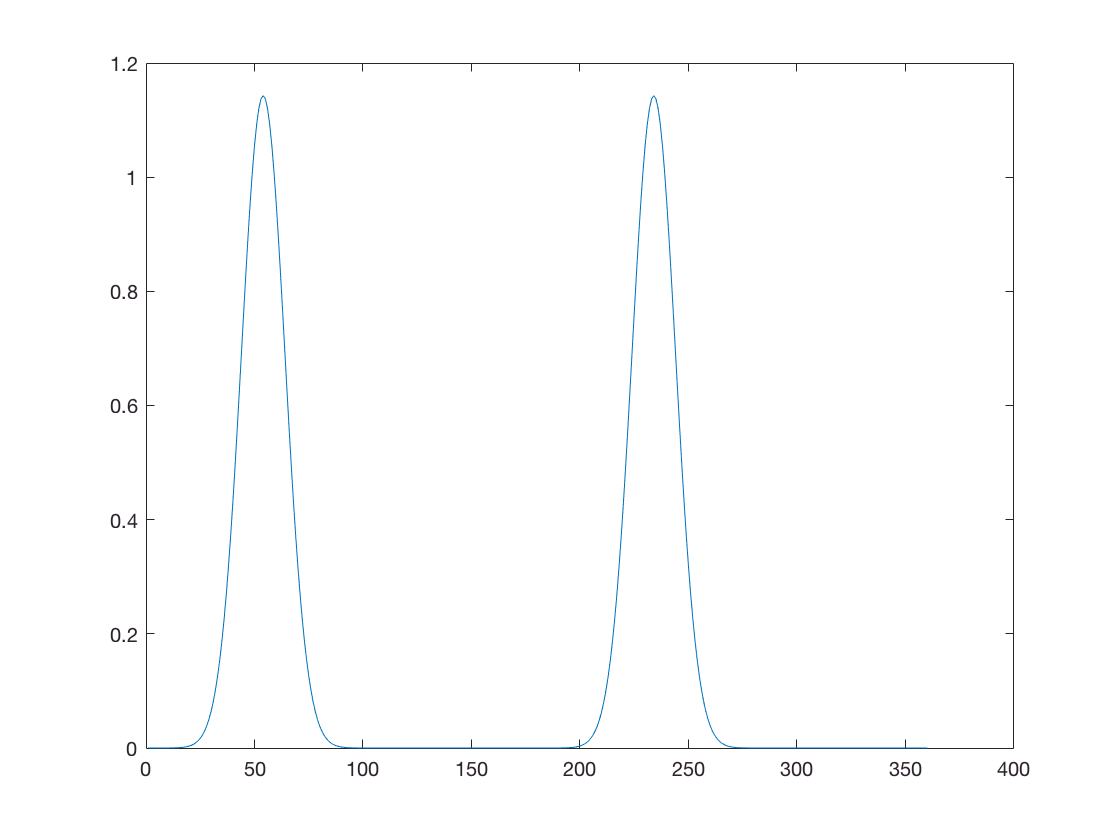

data_point_ = data_point;

data_point_.intensity_data = data_fab;
data_point_ = data_point_.Normalize;
data_point_.odd = circshift(data_point_.odd', -90)';
plot(theta_full*180/pi, data_point_.odd);

data_point_ = data_point_.GenerateFourier(14);
gammaFS = evalFourierRad(data_point_.an, data_point_.bn, 1, theta_full);

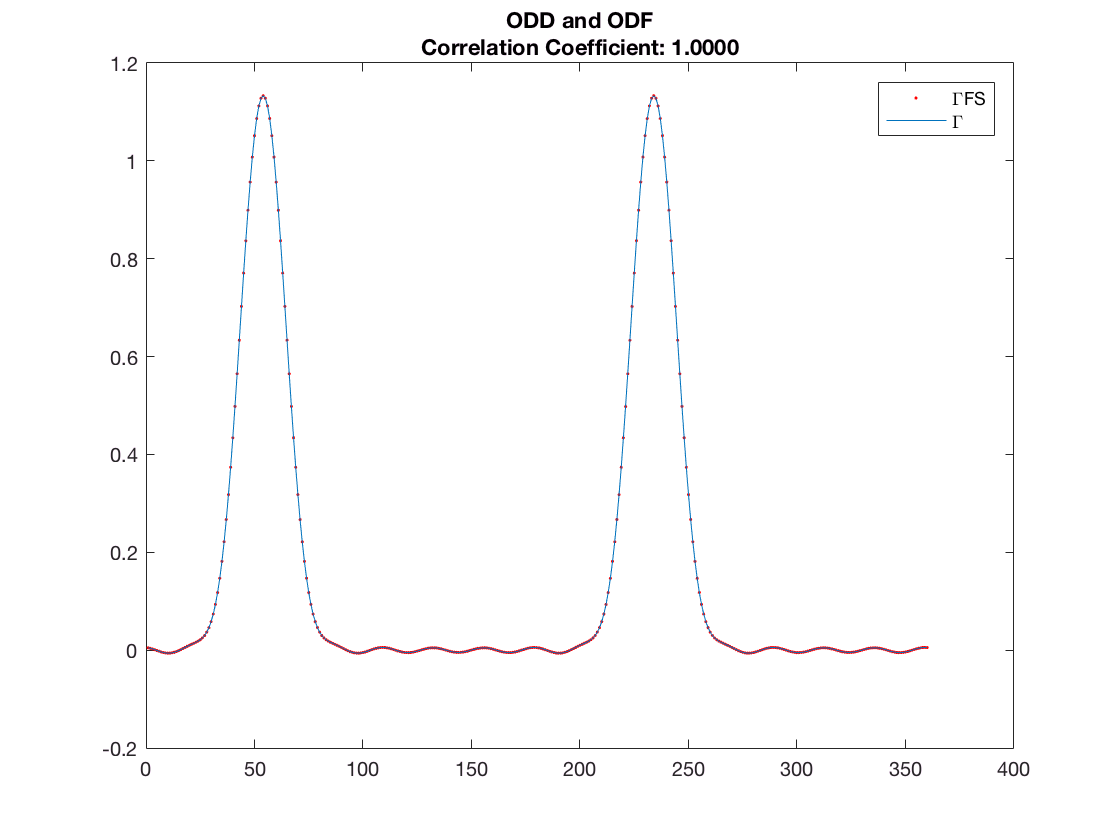

plot(theta_full*180/pi, gammaFS, 'r.', theta_full*180/pi, data_point_.odf);
title(sprintf('ODD and ODF\nCorrelation Coefficient: %0.4f', data_point_.corr_coeff));
legend('\GammaFS', '\Gamma');

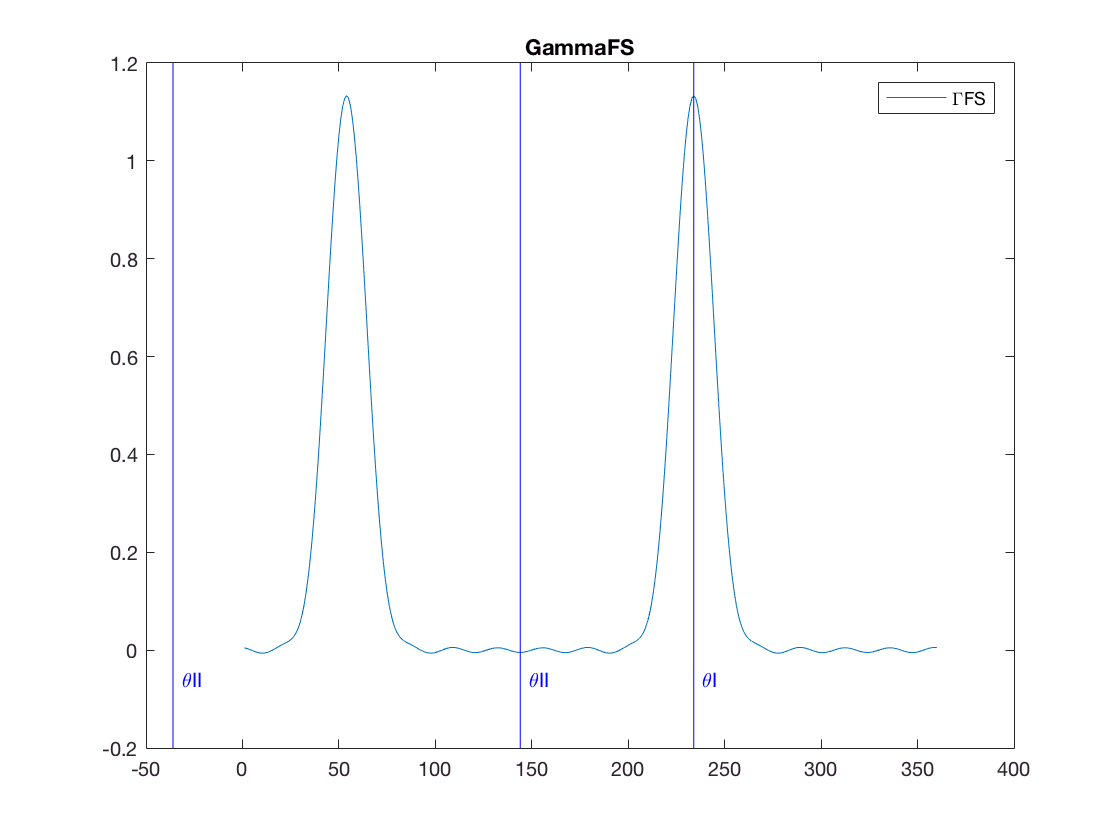

plot(theta_full*180/pi, gammaFS);
[thetaI, thetaII] = data_point_.ComputeSymAngles();
title(sprintf('GammaFS', data_point_.corr_coeff));
vline(thetaI*180/pi + 180, 'b', '\thetaI');
vline(thetaII*180/pi, 'b', '\thetaII'); vline(thetaII*180/pi + 180, 'b', '\thetaII');
legend('\GammaFS');

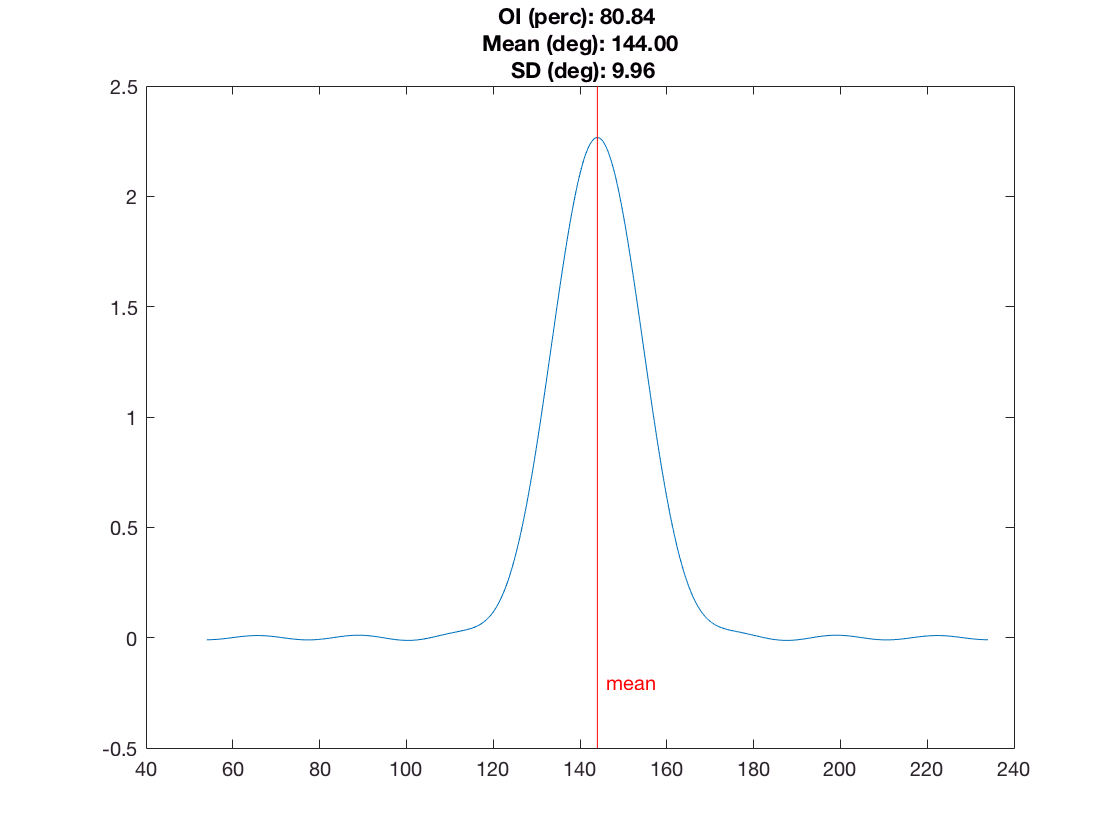

interval = pi/720;
theta = thetaII:interval:thetaII + pi;
odf_FS_fit = evalFourierRad(data_point_.an, data_point_.bn, 2,  theta);

mean = compute_mean(odf_FS_fit, theta);
[oi, sd] = compute_orientation_index(mean, odf_FS_fit, theta);
data_point_.mean_odf = mean*180/pi;
data_point_.oi_odf = oi;
data_point_.sd_odf = sd;

plot(theta*180/pi, odf_FS_fit);

title(sprintf('OI (perc): %.2f \n Mean (deg): %.2f \n SD (deg): %.2f', oi, mean*180/pi, sd*180/pi));
vline(mean*180/pi, 'r', 'mean');

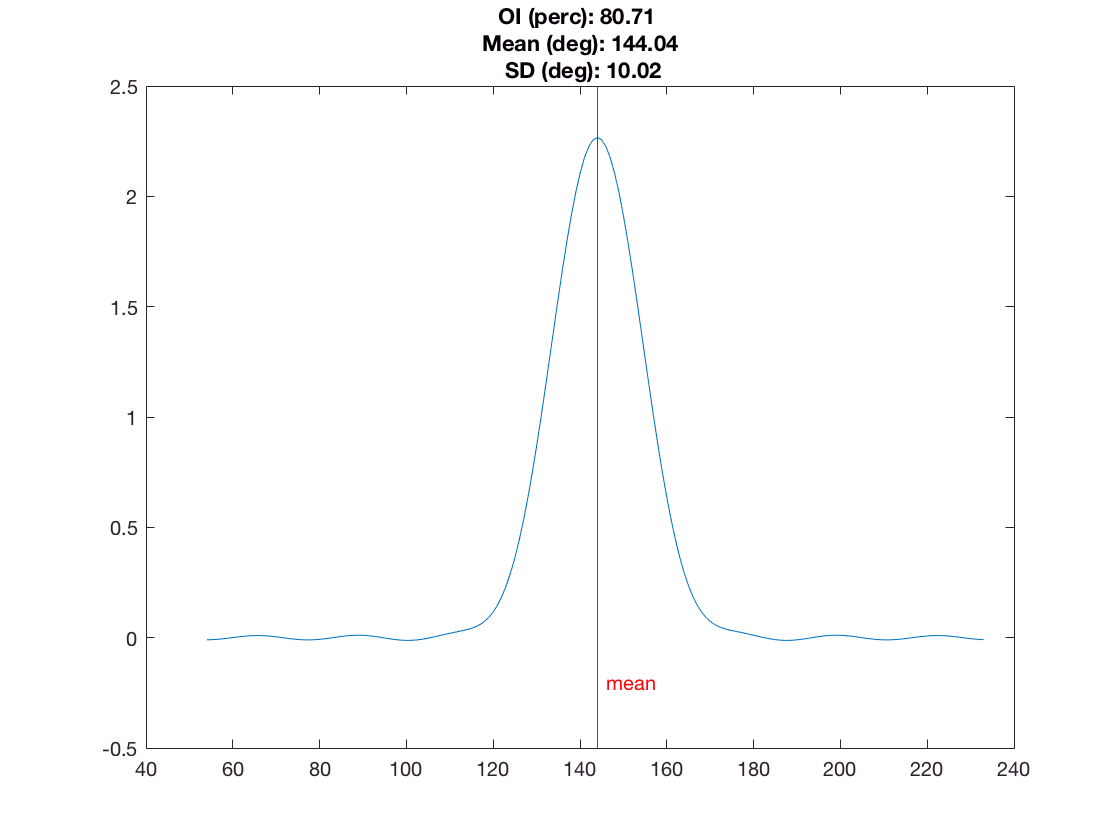

[pi_half_odf, pi_half_odf_range] = data_point_.GetODFPiSegment();

mean_odf = compute_mean(pi_half_odf, pi_half_odf_range);
[oi, sd] = compute_orientation_index(mean_odf, pi_half_odf, pi_half_odf_range);
data_point_.mean_odf = mean_odf*180/pi;
data_point_.oi_odf = oi;
data_point_.sd_odf = sd;

plot(pi_half_odf_range*180/pi, pi_half_odf);

title(sprintf('OI (perc): %.2f \n Mean (deg): %.2f \n SD (deg): %.2f', oi, mean_odf*180/pi, sd*180/pi));
vline(mean_odf*180/pi, 'r', 'mean');

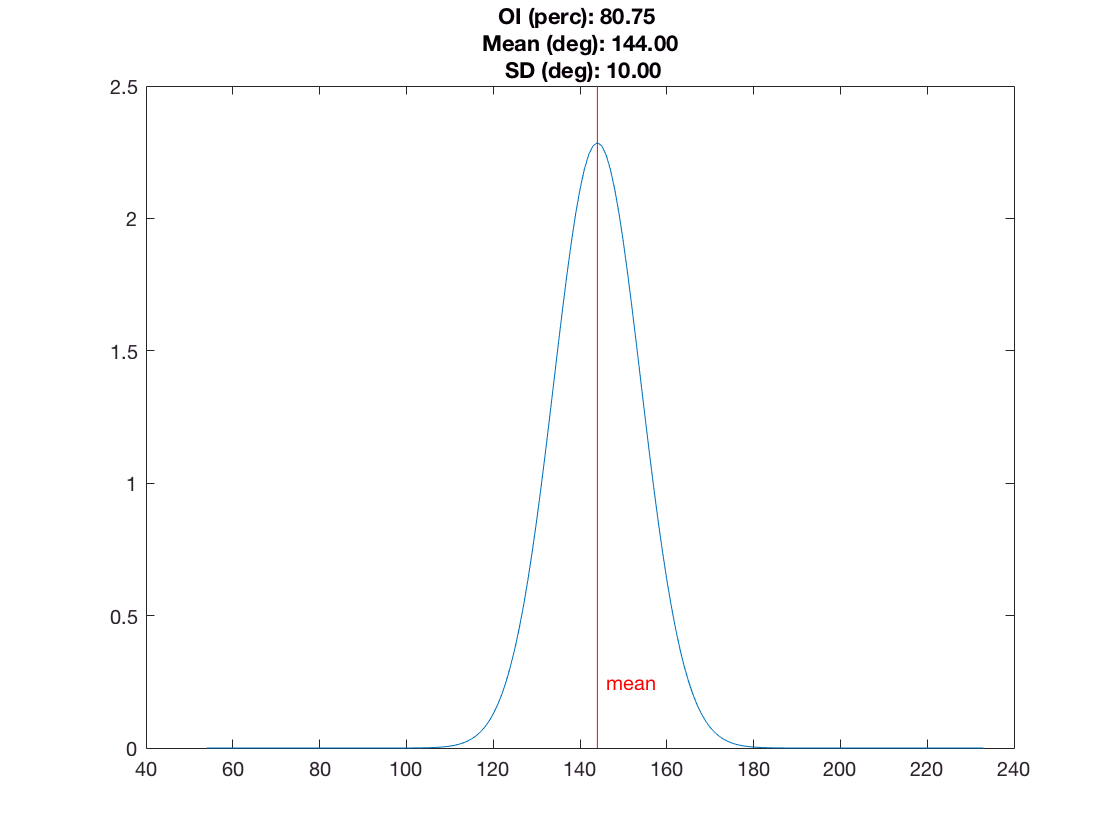

[pi_half_odd, pi_half_odd_range] = data_point_.GetODDPiSegment();

mean_odd = compute_mean(pi_half_odd, pi_half_odd_range);
[oi, sd] = compute_orientation_index(mean_odd, pi_half_odd, pi_half_odd_range);
data_point_.mean_odd = mean_odd*180/pi;
data_point_.oi_odd = oi;
data_point_.sd_odd = sd;

plot(pi_half_odd_range*180/pi, pi_half_odd);

title(sprintf('OI (perc): %.2f \n Mean (deg): %.2f \n SD (deg): %.2f', oi, mean_odd*180/pi, sd*180/pi));
vline(mean_odd*180/pi, 'r', 'mean');